WGG_st.name='WGG';
WGG_st.lat=-33.83;
WGG_st.lon=18.67;
WGG_st.alt=NaN;

t=(Welgegundabsoprtionscattering201109201801{:,1:6});
WGG_rd=timetable(datetime((t)));
WGG_rd.BaR_A=Welgegundabsoprtionscattering201109201801{:,'VarName7'};
WGG_rd.BsB_S=Welgegundabsoprtionscattering201109201801{:,'VarName8'};
WGG_rd.BsG_S=Welgegundabsoprtionscattering201109201801{:,'VarName9'};
WGG_rd.BsR_S=Welgegundabsoprtionscattering201109201801{:,'VarName10'};


namesOK=fieldnames(WGG_rd);
C=startsWith(namesOK,'B');
     N=namesOK(C);
    for i=1:length(N)
         ind=WGG_rd.(N{i})==-999;
     WGG_rd.(N{i})(ind)=NaN;
    end

datevec(WGG_rd.Time(1))

ans =         2011           9           1           0           0           0

datevec(WGG_rd.Time(end))

ans =         2018           1          31          23           0           0

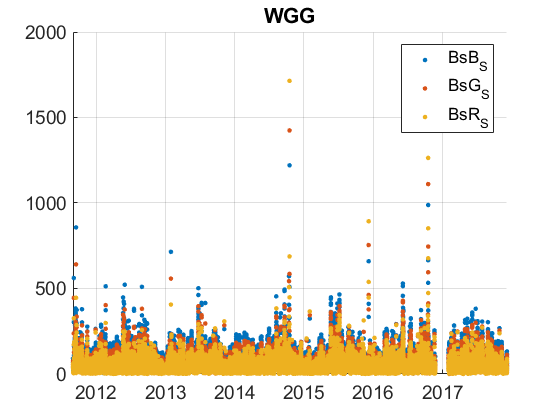

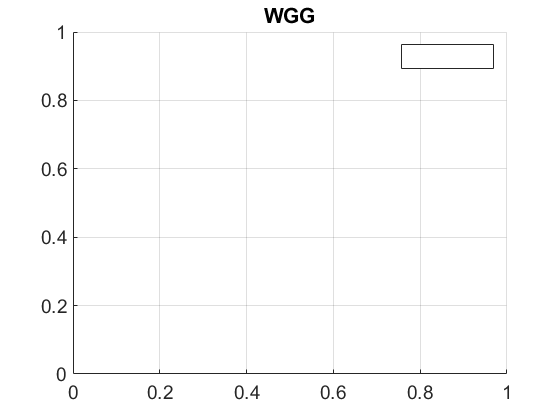

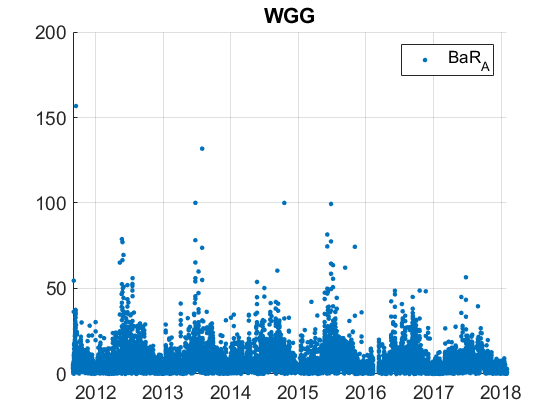

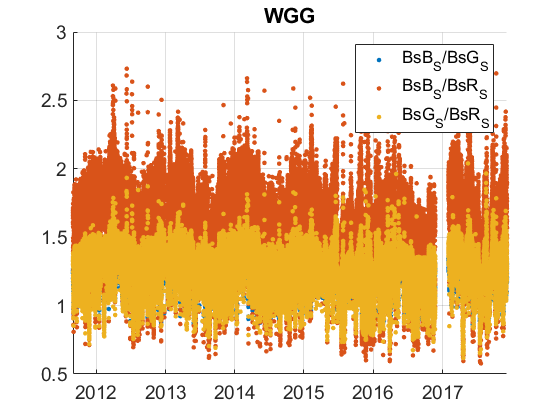

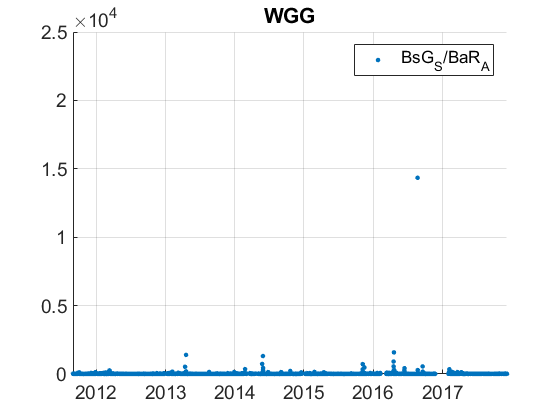

%prctile(WGG_rd.U_S11,[5 50 95])
plotFigControl(WGG_rd,WGG_st.name);

% 1 size cut, 
% sc: ok, no clear seasonal cycle, few negatives
%with RH<50 almost no more data


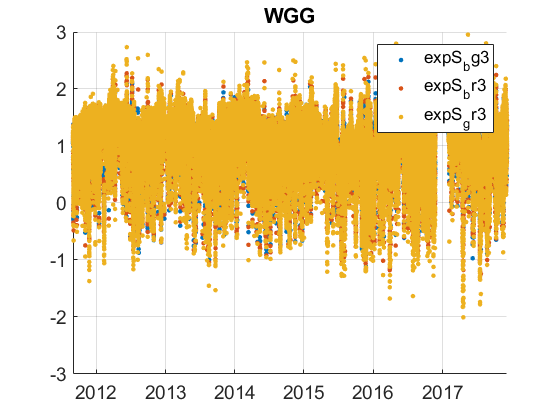

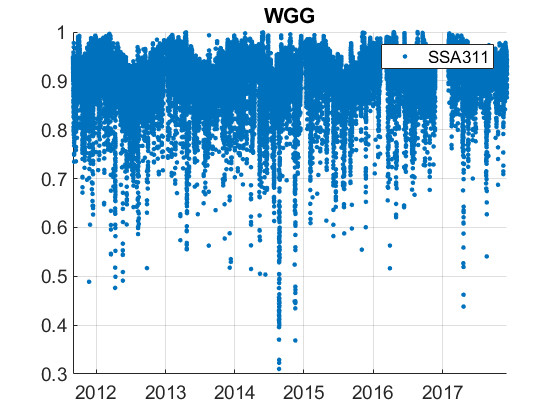

lambdaSC=[450;550;700]*ones(1,4);
lambdaAE=[467;529;653]*ones(1,4);
WGG_cal=compute_exp_SSA(WGG_rd,lambdaSC, lambdaAE);
plotFigControl_cal(WGG_cal,WGG_st.name);

%Questions:
%problems:
%



%scat  begin end March 2008, end July 2017, nothing from mid 2014 to 2017
%abs: begin may 2008, end 31 december 2011
% Rh only in 2013 and 2017
% --> not complete enough (and not long enough) to compute and 